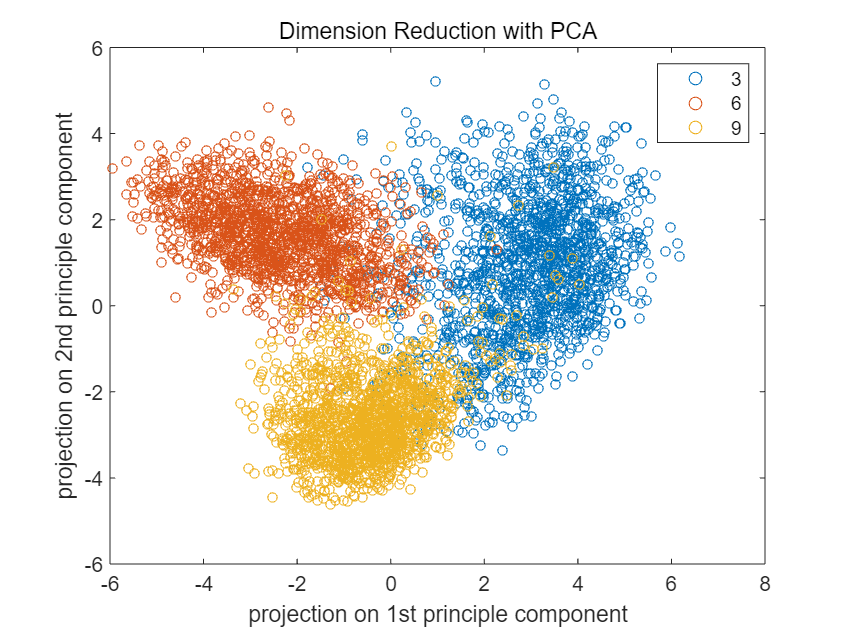

load mnist-3-6-9.mat %each column represent an sample(image)

%Normalize
digitNormalize=[digit3 digit6 digit9];
for i=1:size(digitNormalize,1)
    data=digitNormalize(i,:);
    [data,~]=mapminmax(data,0,1);
    digitNormalize(i,:)=data;
end

%compute mean value matrix
E=mean(digitNormalize,2);%compute mean of each row
E=repmat(E,1,size(digitNormalize,2));

%Subtract the mean
digitNormalize=digitNormalize-E;

%Compute Covariance matrix
C=cov(digitNormalize.');

%compute eigenvectors and eigenvalues
[eigenvectors,eigenvalues]=eigs(C);

%find the first two principal components
eigenvaluesMax=max(abs(eigenvalues));
[principalValue_1,principalValueIndex_1]=max(eigenvaluesMax);
eigenvaluesMax(principalValueIndex_1)=0;
[principalValue_2,principalValueIndex_2]=max(eigenvaluesMax);
principalVector_1=eigenvectors(:,principalValueIndex_1);
principalVector_2=eigenvectors(:,principalValueIndex_2);

%compute projections to the first two principal components
projection_1=principalVector_1.'*digitNormalize;
projection_2=principalVector_2.'*digitNormalize;

%plot
figure(1)
colormap("summer")
scatter(projection_1(:,1:1500),projection_2(:,1:1500),20,'o');hold on
scatter(projection_1(:,1501:3000),projection_2(:,1501:3000),20,'o');hold on
scatter(projection_1(:,3000:4500),projection_2(:,3000:4500),20,'o');hold off
box on
legend('3','6','9');
xlabel('projection on 1st principle component');
ylabel('projection on 2nd principle component');
title('Dimension Reduction with PCA')

save data_PCA projection_1 projection_2